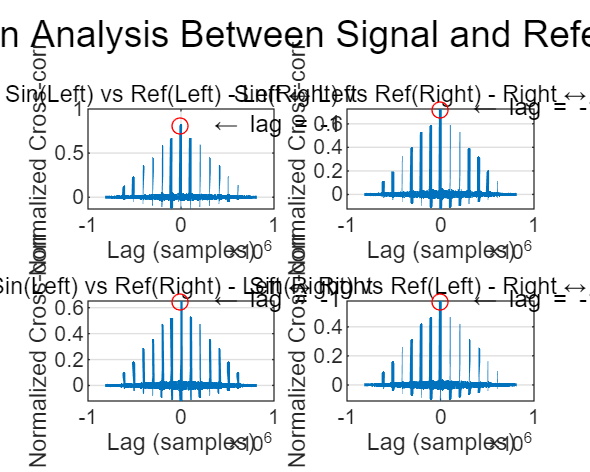

clear; clc; close all;

% Load data
load("Hw2a.mat");  % Contains Sin_x, Sn_ref_x, fs
% load("Hw2b.mat");  % Contains Sin_x, Sn_ref_x, fs
% load("Hw2c.mat");  % Contains Sin_x, Sn_ref_x, fs

Sin_x = Sin_a;
Sn_ref_x = Sn_ref_a;

% Sin_x = Sin_c;
% Sn_ref_x = Sn_ref_c;





% Channel names
names = {'Left', 'Right'};
plot_xcorr(Sin_x, Sn_ref_x, names);

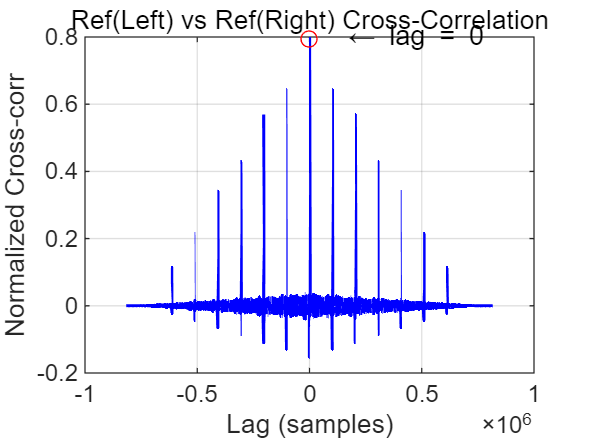



% Cross-correlation between reference channels
[cc_ref, lag_ref] = xcorr(Sn_ref_x(:,1), Sn_ref_x(:,2), 'coeff');

figure('Name','Cross-Correlation Between Reference Channels');
plot(lag_ref, cc_ref, 'b', 'LineWidth', 1.2);
grid on;
xlabel('Lag (samples)');
ylabel('Normalized Cross-corr');
title('Ref(Left) vs Ref(Right) Cross-Correlation');

% Mark peak
[~, idx_ref] = max(abs(cc_ref));
hold on;
plot(lag_ref(idx_ref), cc_ref(idx_ref), 'ro');
text(lag_ref(idx_ref), cc_ref(idx_ref), ['  \leftarrow lag = ', num2str(lag_ref(idx_ref))], 'FontSize', 10);




function plot_xcorr(Sin_x, Sn_ref_x, names)
    pairs = {
        1, 1, 'Left ↔ Left';
        2, 2, 'Right ↔ Right';
        1, 2, 'Left ↔ Right';
        2, 1, 'Right ↔ Left';
    };

    figure('Name','Signal-Reference Cross-Correlation','Position',[100 100 1000 800]);
    for i = 1:4
        ch_s = pairs{i,1};
        ch_r = pairs{i,2};
        label = pairs{i,3};

        [cc, lag] = xcorr(Sin_x(:,ch_s), Sn_ref_x(:,ch_r), 'coeff');
        subplot(2,2,i);
        plot(lag, cc, 'LineWidth', 1.2); grid on;
        xlabel('Lag (samples)');
        ylabel('Normalized Cross-corr');
        title(['Sin(', names{ch_s}, ') vs Ref(', names{ch_r}, ') - ', label]);

        [~, idx] = max(abs(cc));
        hold on;
        plot(lag(idx), cc(idx), 'ro');
        text(lag(idx), cc(idx), ['  \leftarrow lag = ', num2str(lag(idx))], 'FontSize', 9);
    end
    sgtitle('Cross-Correlation Analysis Between Signal and Reference Channels', 'FontSize', 14);
end
